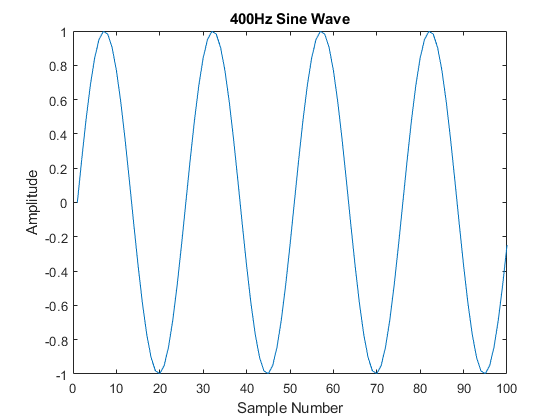

s1 = sine_gen(1.0,400,10000,1);
plot(s1(1:100));
xlabel('Sample Number');
ylabel('Amplitude');
title('400Hz Sine Wave');

s2 = sine_gen(0.5, 1000, 10000, 1.0);
signal = s1 + s2

signal =          0    0.5426    0.9573    1.1601    1.1382    0.9511    0.7041    0.5068    0.4293    0.4766    0.5878    0.6620    0.6009    0.3502   -0.0742   -0.5878   -1.0644   -1.3804   -1.4578   -1.2919   -0.9511   -0.5504   -0.2090   -0.0062    0.0452    0.0000   -0.0452    0.0062    0.2090    0.5504    0.9511    1.2919    1.4578    1.3804    1.0644    0.5878    0.0742   -0.3502   -0.6009   -0.6620   -0.5878   -0.4766   -0.4293   -0.5068   -0.7041   -0.9511   -1.1382   -1.1601   -0.9573   -0.5426


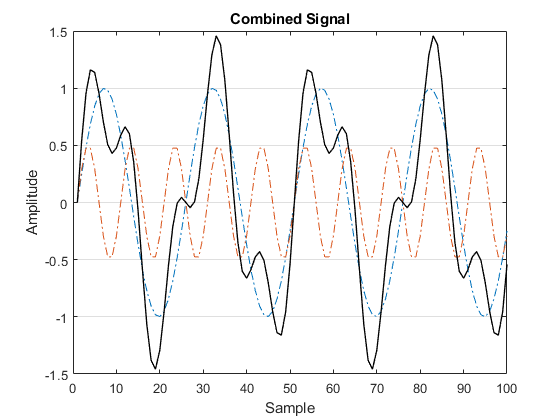

plot(s1(1:100),"LineStyle","-.");
hold on;
plot(s2(1:100),"LineStyle","-.")
hold on;
plot(signal(1:100),"LineWidth",1.0,"Color",[0,0,0]);
hold off;
set(gca,'XGrid','off','YGrid','on')
title('Combined Signal')
xlabel('Sample')
ylabel('Amplitude')

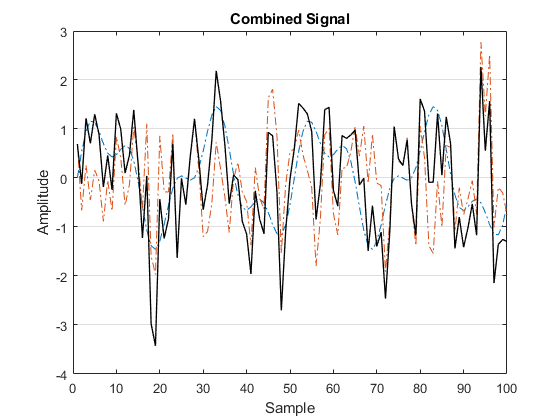

noise_signal = randn(size(s1+s2));
combine_signals(signal, noise_signal);

dot_product_12 = s1*s2'

dot_product_12 = 1.7941e-13

s3 = sine_gen(1.0,401,10000,1);
dot_product_13 = s1*s3'

dot_product_13 = -1.9691e-10

dot_product_121 = (s1+s2)*s1'

dot_product_121 = 5.0000e+03